% close all
% clear variables 

addpath('.\beamforming')
addpath('.\beamforming\algorithm')
addpath('.\beamforming\toolbox')

signal2double = @(signal) double(signal)/double(intmax("int16")); 

% Main params
c = 343;
fs = 16000;
frame_duration = 0.5;

% Beamforming
load array66.mat

steering_type = 4; 
beamform_type = 'Fast-DAS'; 

z_source = [100];

scan_freq = [250 2000]; % the range of scanning frequency
scan_x = [-30,30]; scan_y = [-30,30]; % the range of scanning plane 
scan_resolution = 1; % resolution of scanning plane

mic_x_axis = array(:,1); mic_y_axis = array(:,2); mic_z_axis = 0;
mic_pos = [mic_x_axis mic_y_axis]; mic_pos(:,3) = mic_z_axis;
mic_centre = mean(mic_pos);  % coordinates of the center of the microphone array

% Pan's coord
ref_point = [56.10234300 35.884162 0];
pan_loc_l = [56.09855167 35.874385 0];
pan_loc_r = [56.09771450 35.875883 0];

## Load PAN Data

workdir = 'D:\Sber\sounds\flight_task'; 


% Pan Left

[filearray, patharray] = uigetfile({'*.mat'}, ...
    'Select a array file', workdir);
[fileuav, pathuav] = uigetfile({'*.mat'}, ...
    'Select a uav file', workdir);

filepatharray = fullfile(patharray, filearray);
filepathuav = fullfile(pathuav, fileuav);
[pan_l_data_t, uav_data_t] = read_flight(filepatharray,filepathuav);
uav_coord = extrap_uav_coord(uav_data_t, pan_l_data_t);

pan_l_data_t = removevars(pan_l_data_t,{'Signal_sum'});

pan_l_data = table2array(pan_l_data_t);
pan_l_data = signal2double(pan_l_data);

clear pan_l_data_t uav_data_t

% Pan Right

[filearray, patharray] = uigetfile({'*.mat'}, ...
    'Select a array file', workdir);
[fileuav, pathuav] = uigetfile({'*.mat'}, ...
    'Select a uav file', workdir);

filepatharray = fullfile(patharray, filearray);
filepathuav = fullfile(pathuav, fileuav);
[pan_r_data_t, uav_data_t] = read_flight(filepatharray,filepathuav);

uav_coord = extrap_uav_coord(uav_data_t, pan_r_data_t);

pan_r_data_t = removevars(pan_r_data_t,{'Signal_sum'});

pan_r_data = table2array(pan_r_data_t);
pan_r_data = signal2double(pan_r_data);

clear pan_r_data_t uav_data_t

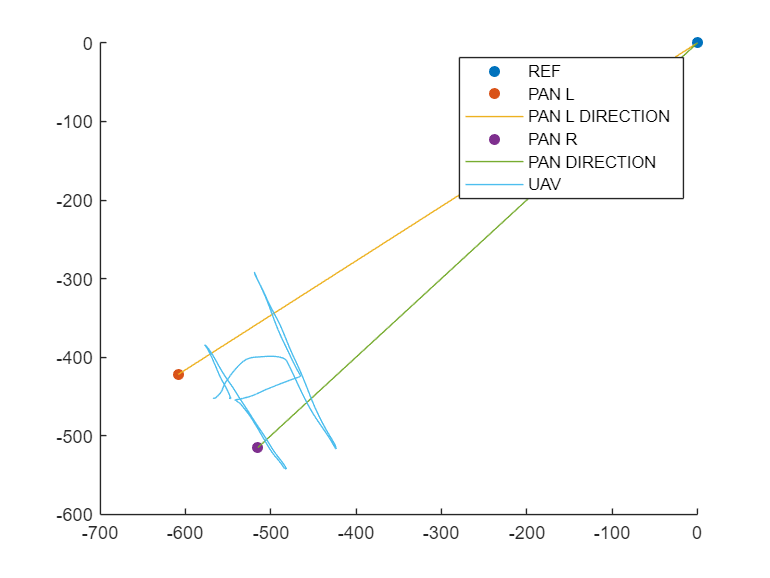

[uav_east, uav_north] = latlon2local(uav_coord.lat, uav_coord.lon, 0, ...
    ref_point);
[ref_point_east, ref_point_north] = latlon2local(ref_point(1), ref_point(2), ref_point(3), ...
    ref_point);
[pan_l_east, pan_l_north] = latlon2local(pan_loc_l(1), pan_loc_l(2), pan_loc_l(3), ...
    ref_point);
[pan_r_east, pan_r_north] = latlon2local(pan_loc_r(1), pan_loc_r(2), pan_loc_r(3), ...
    ref_point);

figure('Name', 'Flight Task Trajectory');
hold on
scatter(ref_point_east, ref_point_north, "filled")
scatter(pan_l_east, pan_l_north, "filled")
plot([ref_point_east pan_l_east], [ref_point_north pan_l_north])
scatter(pan_r_east, pan_r_north, "filled")
plot([ref_point_east pan_r_east], [ref_point_north pan_r_north])
plot(uav_east, uav_north)
legend('REF', 'PAN L', 'PAN L DIRECTION', 'PAN R', 'PAN DIRECTION', 'UAV')

## Beamforming

current_pos =38

current_pos = 38

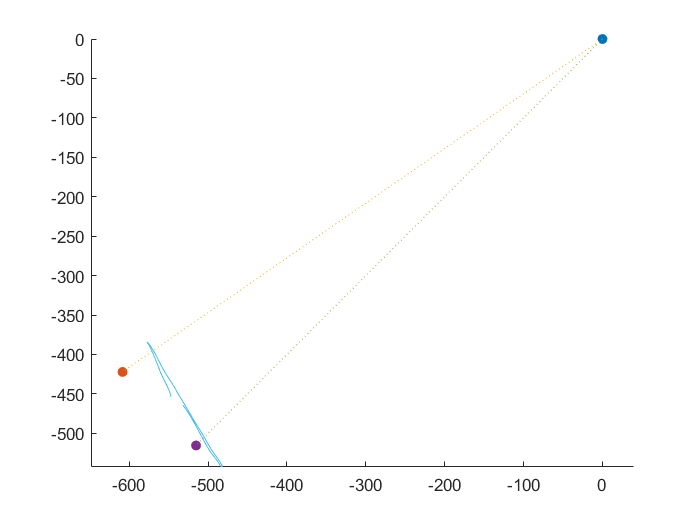

figure('Name', 'Flight Task Trajectory');
hold on
scatter(ref_point_east, ref_point_north, "filled")
scatter(pan_l_east, pan_l_north, "filled")
plot([ref_point_east pan_l_east], [ref_point_north pan_l_north], ':')
scatter(pan_r_east, pan_r_north, "filled")
plot([ref_point_east pan_r_east], [ref_point_north pan_r_north], ':')
pos_idx = round(current_pos*length(uav_east)/100);
plot(uav_east(1:pos_idx), uav_north(1:pos_idx))
axis('equal');

Beamforming

z_dist = z_source(1);

search_freql = scan_freq(1); 
search_frequ = scan_freq(end);

pos_idx = round(current_pos*length(pan_l_data)/100);
pan_l_frame = pan_l_data((pos_idx-frame_duration*fs + 1):pos_idx,:);
[X_l, Y_l, B_l] = beamforming(pan_l_frame, steering_type, beamform_type, fs, z_dist, scan_freq, scan_x, scan_y, scan_resolution, mic_pos, mic_centre);

B_l(B_l<0)=0;
SPL_l = 20*log10((eps+sqrt(real(B_l)))/2e-5);

pos_idx = round(current_pos*length(pan_r_data)/100);
pan_r_frame = pan_r_data((pos_idx-frame_duration*fs + 1):pos_idx,:);
[X_r, Y_r, B_r] = beamforming(pan_r_frame, steering_type, beamform_type, fs, z_dist, scan_freq, scan_x, scan_y, scan_resolution, mic_pos, mic_centre);

B_r(B_r<0)=0;
SPL_r = 20*log10((eps+sqrt(real(B_r)))/2e-5);

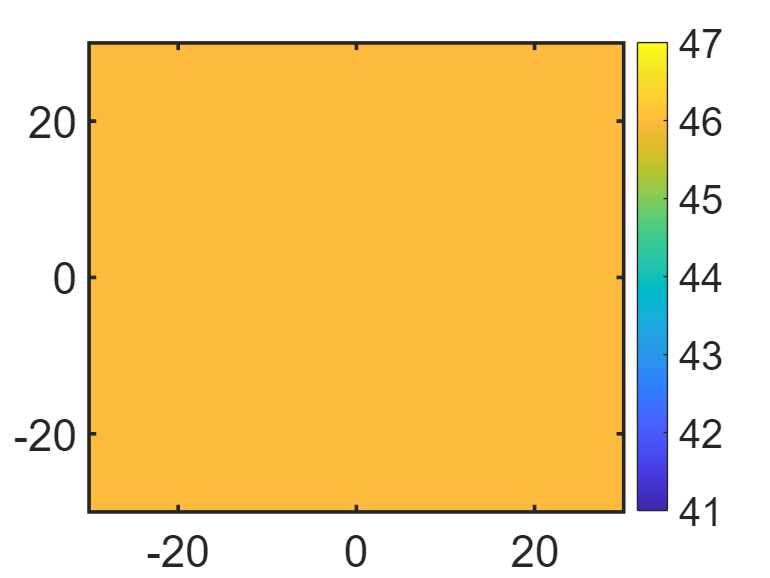

% Plot beamforming map, and see './data_label/label.txt' for ground truth
figure; BF_dr = 6; maxSPL = ceil(max(SPL_l(:)));
contourf(X_l, Y_l, SPL_l, (maxSPL-BF_dr):1:maxSPL); colorbar; clim([maxSPL-BF_dr maxSPL])
% set(gcf,'Position',[20 100 640 500]);	 
set(gca,'FontSize',24); set(gca,'linewidth',2); set(gcf,'Color','w');	
xlim(scan_x); ylim(scan_y);

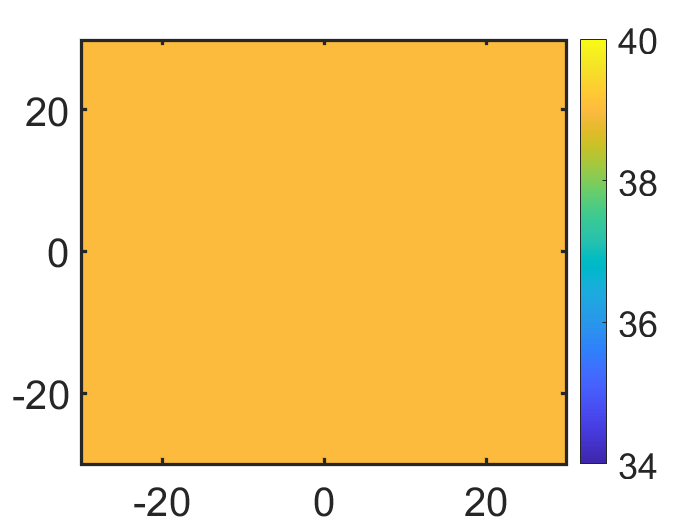


figure; BF_dr = 6; maxSPL = ceil(max(SPL_r(:)));
contourf(X_l, Y_l, SPL_r, (maxSPL-BF_dr):1:maxSPL); colorbar; clim([maxSPL-BF_dr maxSPL])
% set(gcf,'Position',[20 100 640 500]);	 
set(gca,'FontSize',24); set(gca,'linewidth',2); set(gcf,'Color','w');	
xlim(scan_x); ylim(scan_y);